# V768 - Measuring Vision with Psychophysics

## Lab 2 - Signal Detection Theory

**How well can a person distinguish between information and noise?** In this lab, you will learn about signal detection theory (SDT), which gives us a framework that we can use to answer that question.

As a primer, recall the method of constant stimuli experiment from last week's lab. In most trials, a grating (signal) was present, but in some, the grating was set to have the same luminance as the background. Likewise, you probably reported seeing (detecting) a grating in most trials but reported not seeing a grating in some. We could use that information to divide those trials into four groups:

By the end of this tutorial, you will understand how classifying responses as hits, misses, false alarms, and correct rejections allows you to calculate the detectabilty of a particular stimulus for an observer.

*Based on *[*https://gru.stanford.edu/doku.php/tutorials/sdt*](https://gru.stanford.edu/doku.php/tutorials/sdt)* by Justin Gardner, Stanford University.*

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Define and calculate hits, misses, false alarms, and correct rejections.

- Explain the role of the criterion in determining the number of hits, misses, false alarms and correct rejections.

- Calculate d-prime. Describe how this measure of sensitivity can be independent of the decision criterion of the observer.

### Questions

#### A. Simulate a Signal Detection Experiment

- In your own words, explain the x-axis of signal detection distributions.

#### B. Analyze Simulated Data

- What are the two ways to be "right" in a signal detection experiment?

- Include and write a figure caption for the 3-panel figure in Part B, Step 1.

- Report the results from Part B (hits, misses, false alarms, and correct rejections) in table form, and write a description of the results, including an explanation of the significance of each number.

#### C. Test the Impact of the Criterion Value

- Include and write a figure caption for the figure in Part C, Step 1.

- Include and write figure captions for the two figures in Part C, Step 2.

- Describe how changing the observer's decision criterion affects the observer's performance.

- Do you think that there is a relationship between the observer's decision criterion and d'? Why, or why not?

#### D. Test the Impact of d'

- Include and write a figure caption for the figure in Part D, Step 1.

- Include and write a figure caption for the figure in Part D, Step 2.

- Describe how changing the observer's d' affects the observer's performance.

#### E. Wrap-Up

- Describe the process of simulating an experiment, and discuss what we can learn from simulations.

## Part A. Simulate a Signal Detection Experiment

A useful approach to better understanding any decision model, experimental method, or analysis tool is building a simulation. Simulations allow you to control and play around with the variables involved to see what effect any particular change has. Therefore, today we are going to simulate a signal detection experiment. For convenience, let's call our simulated observer Turtle.

%                              ___-------___
%                          _-~~             ~~-_
%                       _-~                    /~-_
%    /^\__/^\         /~  \                   /    \
%  /|  O|| O|        /      \_______________/        \
% | |___||__|      /       /                \          \
% |          \    /      /                    \          \
% |   (_______) /______/                        \_________ \
% |         / /         \                      /            \
%  \         \^\\         \                  /               \     /
%    \         ||           \______________/      _-_       //\__//
%      \       ||------_-~~-_ ------------- \ --/~   ~\    || __/
%        ~-----||====/~     |==================|       |/~~~~~
%         (_(__/  ./     /                    \_\      \.
%                (_(___/                         \_____)_)

**What is a signal detection experiment?** Any task that requires an observer to try to detect the presence of a signal. For example, can you see if a candle is lit in a window from 1 mile away? Can you see a friend's face within a crowd? Sometimes these experiments are called “Yes / No” experiments since the observer has to say either “Yes” they saw it or “No” they did not. In these experiments, the signal is present in some trials (signal-present trials) and absent in others (signal-absent trials).

### Step 1. Build a set of trials

First, we need to create a set of trials. We want half of them to be **signal-present** and half to be **signal-absent** (i.e., noise), but we also want to randomize the order of trials (vs. have our simulated observer Turtle complete all signal-present trials followed by all signal-absent trials).

% how many trials to simulate?
n_trials = 5000;

% make half of the trials signal-present (1) and half signal-absent (0)
trial_type = logical([ones(n_trials/2,1); zeros(n_trials/2,1)]);

% shuffle the trials' order
random_order = randperm(n_trials);
trial_type = trial_type(random_order);

#### Check trial counts

When building a simulation, it's always good to double check the results of your programming to make sure that things are working out the way you expected, so let's double check the number of trials of each type included in our list of trials (`trial_type`).

% count trials per type
n_present = sum(trial_type==1);
n_absent = sum(trial_type==0);

% display counts
fprintf(['number of signal-present trials: %i\n', ...
    'number of signal-absent trials:  %i\n'], n_present, n_absent)

number of signal-present trials: 2500
number of signal-absent trials:  2500


### Step 2. Simulate observer's perception

#### The scale of signal perception

Think back to the method of constant stimuli experiment from last week's lab. During each trial, you had to decide whether or not you saw a grating. Your level of confidence that a signal was present likely varied quite a bit, certainly ***across*** the levels of contrast but potentially even ***within*** each contrast level. For each trial, imagine plotting your level of confidence along a number line, like so:

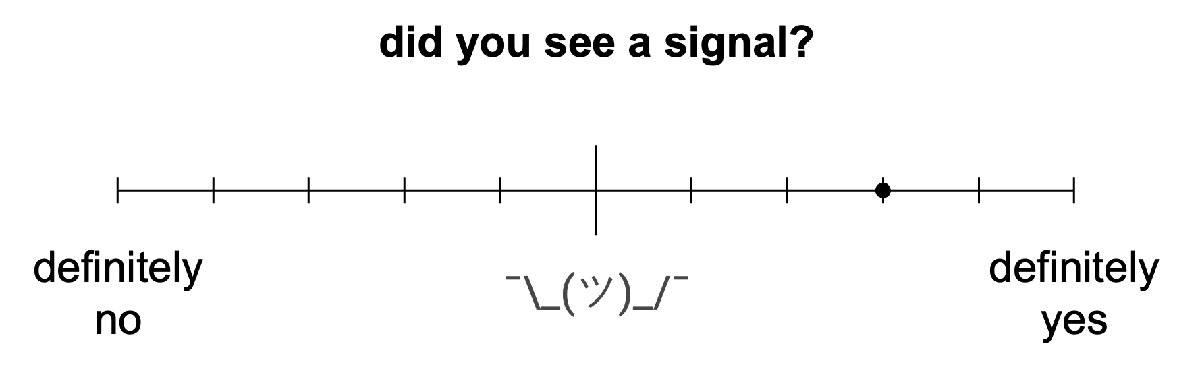

If you repeat that exercise for multiple trials (at the same contrast level), you can plot the distribution of your confidence levels:

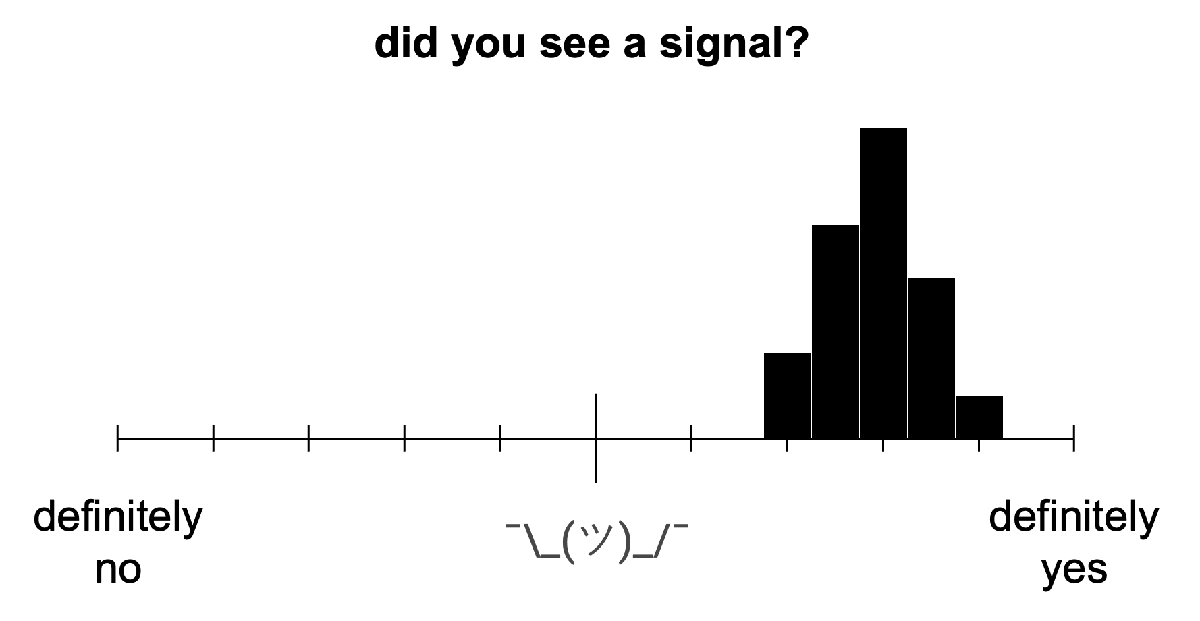

Think of these plots as visual representations of **internal signal strength**. In other words, we aren't plotting the ***actual*** strength of the stimulus, rather we're plotting how visible (or invisible) the stimulus was ***to you***. Moreover, we're plotting the ***variability*** of your perception of the stimulus's strength. When shown the same stimulus over and over, neurons won't always respond the same amount. Likewise, you won't always perceive a particular stimulus the same way each time that you see it. (That's one reason why we include multiple repeats of trials in experiments!) This variability is due to your visual system's **internal noise**.

#### Simulating distributions of percepts

To account for the presence of this internal noise, we want to simulate our observer Turtle's internal signal strength per trial. We can then use their internal signal strength to determine their choice per trial.

Let's assume that Turtle's perception of signal-present trials follows one Gaussian (i.e., normal) distribution and that Turtle's perception of signal-absent trials follows a different, independent Gaussian distribution. Further, let's assume that those two distributions have ***different*** means but the ***same*** standard deviation. In other words, let's assume that Turtle's two sets of internal signal strengths are **independent and identically distributed (IID)**.

% define distribution parameters
dist_stdev = 1;
dist_mean_present = 1;
dist_mean_absent = -1;

% initialize array for observer's internal signal strength per trial
internal_signal = nan(1,n_trials);

% loop over every trial, simulating observer's percept for each
for ii = 1:n_trials
  % determine whether signal was present in the i-th trial
  % to determine which distribution to pull from
  if trial_type(ii) == 1
    % randomly draw from the signal-present distribution
    % (a normal distribution with a specified mean and standard deviation)
    internal_signal(ii) = random('norm',dist_mean_present,dist_stdev);
  else
    % randomly draw from the signal-absent distribution
    internal_signal(ii) = random('norm',dist_mean_absent,dist_stdev);
  end

end

#### Check simulated distributions

To make sure that our simulation is working as expected, we can numerically confirm that the means and standard deviations of the signal-present and signal-absent distributions are what they should be.

disp(array2table([ ...
    mean(internal_signal(trial_type==1)), ...  % calculate mean of signal present distribution
    std(internal_signal(trial_type==1)); ...  % calculate std of signal present distribution
    mean(internal_signal(trial_type==0)), ...  % calculate mean of signal absent distribution
    std(internal_signal(trial_type==0))], ...  % calculate std of signal absent distribution
    'VariableNames',["mean", "stdev"], ...
    'RowNames',["signal-present", "signal-absent"]))

                        mean       stdev 
                      ________    _______

    signal-present     0.95467    0.99243
    signal-absent     -0.98939    0.98709



These numbers should be close to the means and standard deviations that we selected, but they likely do not ***exactly*** match them. This is because we randomly selected numbers from the distributions to better simulate the randomness and variability of a real observer's perception during an experiment.

#### Plot simulated distributions of internal signal strength

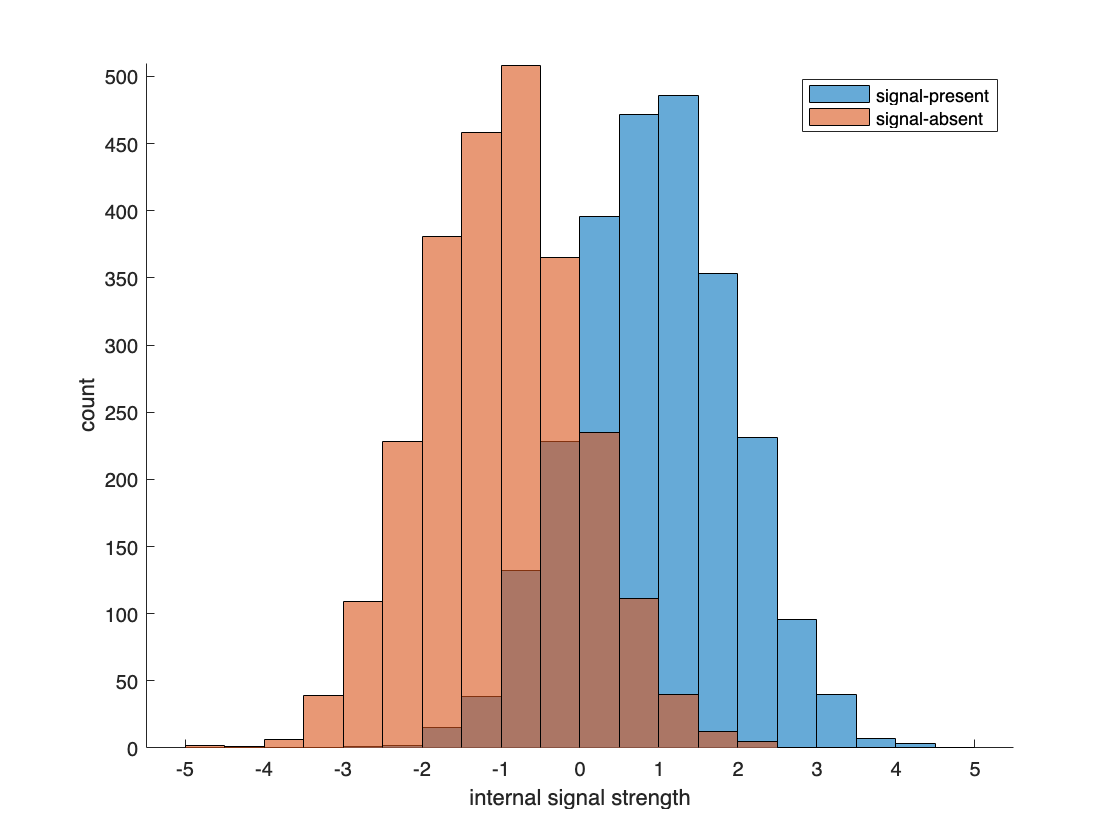

figure; hold on

% define histogram bins to use for both trial types
histogram_bins = -5:.5:5;

% plot signal present distribution
h_present = histogram(internal_signal(trial_type==1),histogram_bins);

% plot signal absent distribution
h_absent = histogram(internal_signal(trial_type==0),histogram_bins);

xlabel('internal signal strength')
ylabel('count')
legend('signal-present','signal-absent')
box off
histogram_max = ceil(max([h_present.Values,h_absent.Values])/10)*10;
ylim([0,histogram_max])

drawnow

### Step 3. Simulate observer's decision-making

Now that we know Turtle's internal signal strength per trial, we need to determine which of the two alternatives ("Yes" vs. "No") Turtle would choose per trial. To make that determination, we need to define Turtle's **decision criterion**. A decision criterion is the internal signal strength threshold an observer uses to decide between two alternatives. Ideally, an observer will report that the signal was present when their internal signal strength is above that threshold, and when their internal signal strength is below that threshold, they will report that the signal was absent.

Turtle's criterion could fall anywhere along the scale from "definitely no" to "definitely yes", but for now, let's place Turtle's criterion exactly in the middle of the means of our two distributions.

criterion = mean([dist_mean_present, dist_mean_absent]);

% calculate the ideal observer response
% (1 = signal present; 0 = signal absent)
response = internal_signal >= criterion;

#### Check response counts

Because we placed Turtle's criterion exactly in the middle of our distributions, we can reasonably expect that the criterion fell roughly in the middle of all of the internal signal strengths we "observed". That would mean that Turtle likely responded "Yes" on approximately half of trials and "No" on approximately half. Let's check whether that is indeed the case.

% display counts
fprintf(['number of "Yes" responses: %i\n', ...
    'number of "No" responses:  %i\n'], ...
    sum(response==1), ...
    sum(response==0))

number of "Yes" responses: 2487
number of "No" responses:  2513


## Part B. Analyze Simulated Data

### Step 1. Identify hits, misses, false alarms, and correct rejections

Each trial in a signal detection experiment has four possible outcomes:

- **Hit** = the signal was present and the observer ***correctly*** responded "Yes"

- **Miss** = the signal was present and the observer ***incorrectly*** responded "No" (aka type II or beta error)

- **False alarm** = the signal was absent and the observer ***incorrectly*** responded "Yes" (aka type I or alpha error)

- **Correct rejection** = the signal was absent and the observer ***correctly*** responded "No"

We often visualize these components, which form the core of signal detection theory, like this: 

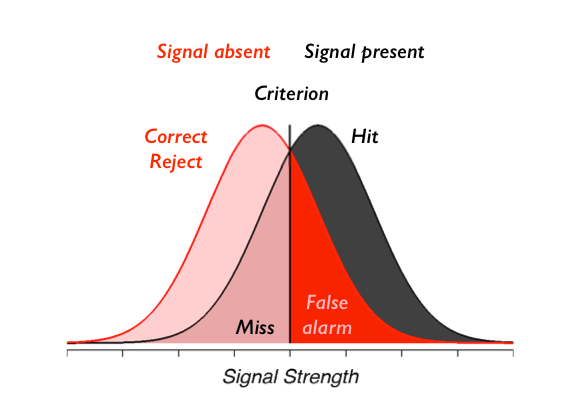

As this diagram shows, an observer's **decision criterion** determines their rates of hits, misses, false alarms, and correct rejections.

***Important to note:*** An observer's performance is impacted by both their decision criterion and their signal strength distributions. However, only the signal strength distributions are perceptually-driven; the criterion value is a cognitive factor. Thus, from the perspective of scientists interested in studying perception, criterion values are confounding factors. This was a key motivator in the development of signal detection theory. A crucial goal was measuring an observer's sensitivity (how good an observer is at detecting a signal) in a way that accounted for this cognitive factor. Before we work through how signal detection theory allows us to accomplish that, let's take a look at our Turtle's performance in the simulation.

**Visualize observer's performance**

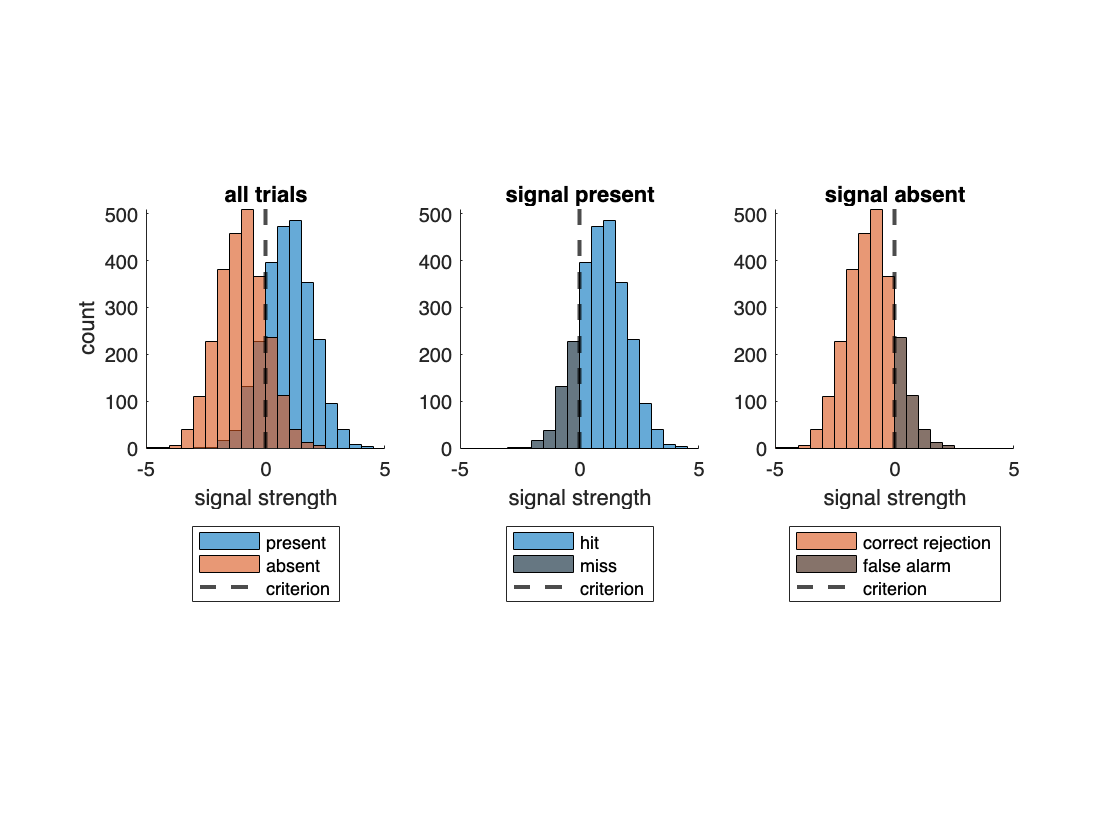

figure

histogram_bins = -5:.5:5;
colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];

% plot the criterion with the two distributions
subplot(131); hold on;
histogram(internal_signal(trial_type==1),histogram_bins)  % present
histogram(internal_signal(trial_type==0),histogram_bins)  % absent
xline(criterion,'k--','LineWidth',2)  % criterion
legend('present','absent','criterion', ...
    'Location','southoutside')
title('all trials')
xlabel('signal strength')
ylabel('count')
ylim([0,histogram_max])
box off; axis square;

% plot signal-present trials (hits and misses)
subplot(132); hold on;
histogram(internal_signal(trial_type==1 & response'==1),histogram_bins, ...
    'FaceColor',colors(1,:))  % hits
histogram(internal_signal(trial_type==1 & response'==0),histogram_bins, ...
    'FaceColor',colors(1,:)*.25)  % misses
xline(criterion,'k--','LineWidth',2)  % criterion
legend('hit','miss','criterion', ...
    'Location','southoutside')
title('signal present')
xlabel('signal strength')
ylim([0,histogram_max])
box off; axis square;

% plot signal-absent trials (false alarms and correct rejections)
subplot(133); hold on;
histogram(internal_signal(trial_type==0 & response'==0),histogram_bins, ...
    'FaceColor',colors(2,:))  % correct rejections
histogram(internal_signal(trial_type==0 & response'==1),histogram_bins, ...
    'FaceColor',colors(2,:)*.25)  % false alarms
xline(criterion,'k--','LineWidth',2)  % criterion
legend('correct rejection','false alarm','criterion', ...
    'Location','southoutside')
title('signal absent')
xlabel('signal strength')
ylim([0,histogram_max])
box off; axis square;

drawnow

#### Count occurences of each possible outcome

We now have a visual sense of how many hits, misses, false alarms, and correct rejections are in our simulated data, but let's count them to get more precise.

n_hit = sum(response(trial_type==1)==1);
n_miss = sum(response(trial_type==1)==0);
n_false_alarm = sum(response(trial_type==0)==1);
n_correct_reject = sum(response(trial_type==0)==0);

% display results in table form
disp(array2table([n_hit, n_miss; n_false_alarm, n_correct_reject], ...
    'VariableNames',["detected", "not detected"], ...
    'RowNames',["signal present", "signal absent"]))

                      detected    not detected
                      ________    ____________

    signal present      2084           416    
    signal absent        403          2097    



#### Calculate rates of each possible outcome

Now we know how many trials fall into the two halves of our signal-present and signal-absent histograms, but what **proportion **of each histogram is on the left vs. right side of the criterion?

% of signal-present trials, what proportion were hits/misses?
hit_rate = n_hit/n_present;
miss_rate = n_miss/n_present;

% of signal-absent trials, what proportion were false alarms/correct rejections?
false_alarm_rate = n_false_alarm/n_absent;
correct_reject_rate = n_correct_reject/n_absent;

% display results in table form
disp(array2table([hit_rate, miss_rate; false_alarm_rate, correct_reject_rate], ...
    'VariableNames',["detected", "not detected"], ...
    'RowNames',["signal present", "signal absent"]))

                      detected    not detected
                      ________    ____________

    signal present     0.8336        0.1664   
    signal absent      0.1612        0.8388   



These numbers tell us the area under either the signal-present or signal-absent curve occupied by each outcome. Importantly, these **area under the curve (AUC)** values can be used to determine **z-scores**. Essentially, a z-score tells you how many standard deviations above or below the mean that a particular value is. Usually means and standard deviations are used to find z-scores, but luckily for us, we can obtain a z-score with just the area under the curve (no knowledge of mean or standard deviation required!). (We'll get to why this is important very soon...)

As a concrete example, let's say that 84% of signal-present trials were hits (i.e., AUC = 0.84). That percentile corresponds to a z-score of 1. Thus, z(Hits) = 1. This indicates that the criterion value (which splits the signal-present distribution into hits and misses) is 1 standard deviation away from the mean of the signal-present distribution.

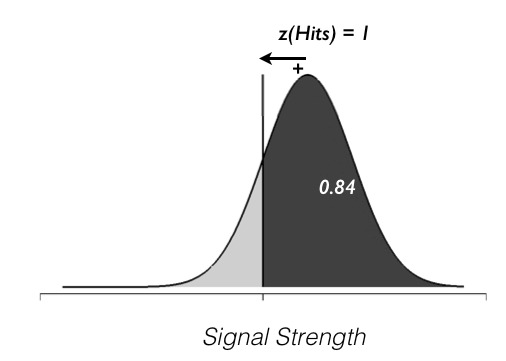

### Step 2. Calculate observer's sensitivity

Now that we've evaluated our observer's performance on our signal detection task, we can work on evaluating their sensitivity to the signal (i.e., how detectable the signal was from the observer's perspective).

To measure an observer's sensitivity independent of their decision criterion, we need to calculate **d'** (aka d-prime). d' is the difference in the means of the signal and noise distributions (i.e., the signal-present and signal-absent distributions) divided by their standard deviation (i.e., width, variability).

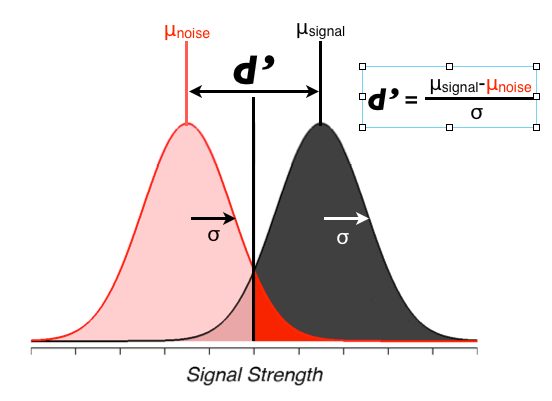

**What does this equation accomplish? **The numerator takes the difference in the distributions' central locations into account, quantifying how far apart they are on the scale of signal perception strength. The denominator takes the distributions' spread into account, quantifying how concentrated the distributions are around their central locations.

Put simply, **d' = separation / spread**.

#### Check your understanding

Consider the following three examples. From the first (top) to the second (middle), only the mean of the noise distribution (gray) changes. From the second (middle) to the third (bottom), only the variability (width) of the distributions changes. **How do these changes affect d'?**

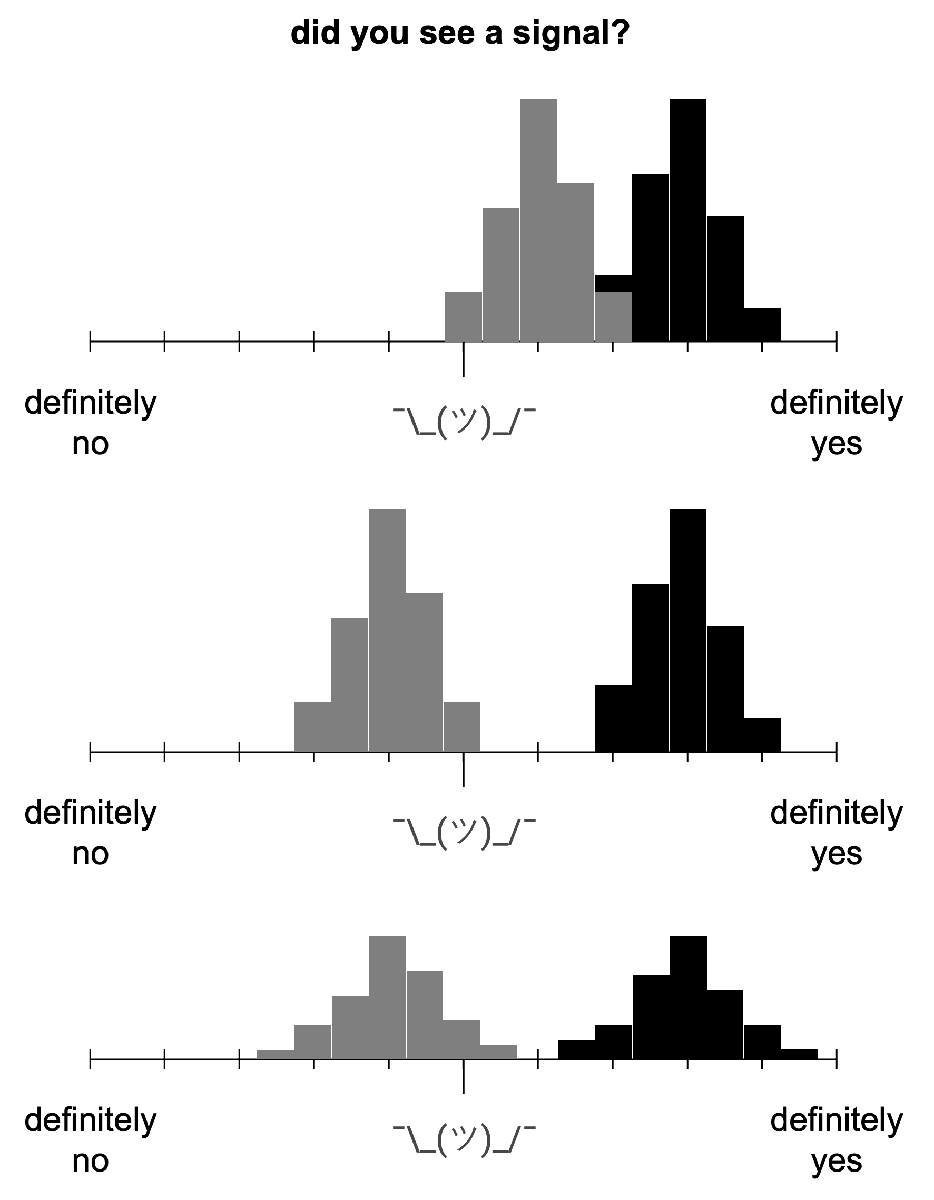

***... Ready to check your understanding? ...***

**Okay, so how do these changes affect d'?**

- From the first example to the second, the distance between the means increases. Thus, the numerator increases, and d' will be larger.

- From the second example to the third, the variability increases. Thus, the denominator increases, and d' will be smaller.

#### How can trial outcomes be used to calculate d'?

Now you know how to calculate d' when we know the means and standard deviations of the signal and noise distributions, but the crux of the problem is that we don't know what those values are in a real experiment. Rather, for each trial, we know the condition (signal present vs. absent), how the observer responded, and thus whether the trial was a hit, miss, false alarm, or correct rejection. This begs the question,** how do we calculate d-prime with just hits, misses, false alarms, and correct rejections?**

The answer to that question involves z-scores. As we covered above, a z-score tells you how many standard deviations above or below the mean that a particular value is, and importantly for this case, z-scores are related to the area under a curve.

We've already looked at an example showing z(Hits). Recall that **z(Hits)** represents the distance (in units of standard deviation) between the criterion value and the mean of the **signal-present** distribution.

Similarly, **-z(False Alarms)** represents the distance (in units of standard deviation) between the criterion value and the mean of the **signal-absent** distribution. (*Note: We use the negative false alarm z-score here because the criterion is on the opposite side of this distribution. Specifically, the criterion is to the left of the signal-present distribution but to the right of the signal-absent distribution.*)

Therefore, the distance between the mean of the signal-present distribution and the mean of the signal-absent distribution (in units of standard deviation) is equal to the sum of z(Hits) and -z(False Alarms). And what variable represents the distance between these distributions, normalized by the standard deviation? **d'**! Thus, **d' = z(Hits) - z(False Alarms)**.

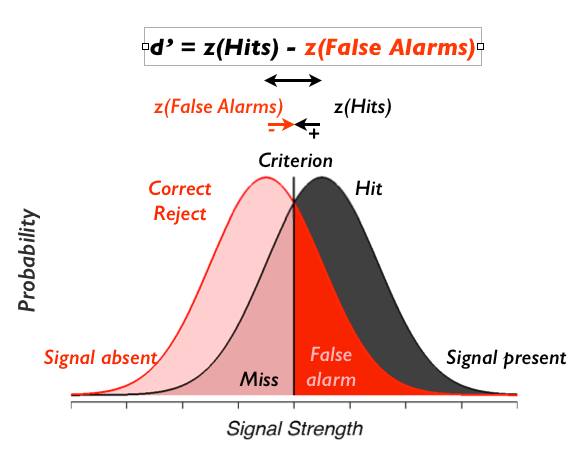

(*FYI: In some places, you may instead see d' = z(False Alarms) - z(Hits). Which equation is "right" vs. "wrong" depends on whether left- or right-tailed z-scores are used. That distinction is worth paying attention to if you're ever setting up these calculations yourself, but for this lab, you can forget all about it.*)

#### Use trial outcomes to calculate d'

Now that we know **d' = z(Hits) - z(False Alarms)**, let's find Turtle's d'!

We first need to calculate z-scores for our hit and false alarm rates. These rates correspond to specific areas underneath Gaussian probability density functions (AUC values). Given a particular z-score, we can use the cumulative density function (CDF) of a normalized Gaussian distribution (i.e., a normal distribution with a mean of 0 and standard deviation of 1) to find the corresponding AUC. Thus, given a particular AUC, we can use the inverse CDF of a normalized Gaussian to find the corresponding z-score.

Once we get the two z-scores we need, all we need to do is subtract them, and then we'll have the observer's d' value.

% get z-scores using the inverse cumulative density function
z_hits = icdf('norm',hit_rate,0,1);
z_false_alarms = icdf('norm',false_alarm_rate,0,1);

% calculate d' using z-scores
d_prime = z_hits - z_false_alarms;

% plug values into d' equation & display result
fprintf('d'' = z(H) - z(FA)\n%.2f = %.2f - %.2f\n', d_prime,z_hits,z_false_alarms)

d' = z(H) - z(FA)
1.96 = 0.97 - -0.99


## Part C. Test the Impact of the Criterion Value

In trying to understand d', you may ask yourself, **does d' depend on the decision criterion?** In other words, is the d-prime measurement sensitive in any systematic way to changes in the criterion?

### Step 1. Determine what you expect to find

We've already touched on how the parameters of the signal and noise distributions can impact d', but when we simulated Turtle's decision-making above, we placed their criterion exactly in between the distributions' means and left it there. What would happen if Turtle increased their criterion and only reported detecting the signal when absolutely sure? What if instead Turtle tried to minimize misses by lowering their criterion?

Try thinking through the impact of both of these changes on Turtle's rates of hits, misses, false alarms, and correct rejections as well as what the impact would be on d'.

#### Plot the signal and noise distributions with different criterion values

Since visuals are often helpful, let's plot Turtle's signal-present and signal-absent distributions again, and let's plot several different criterion values.

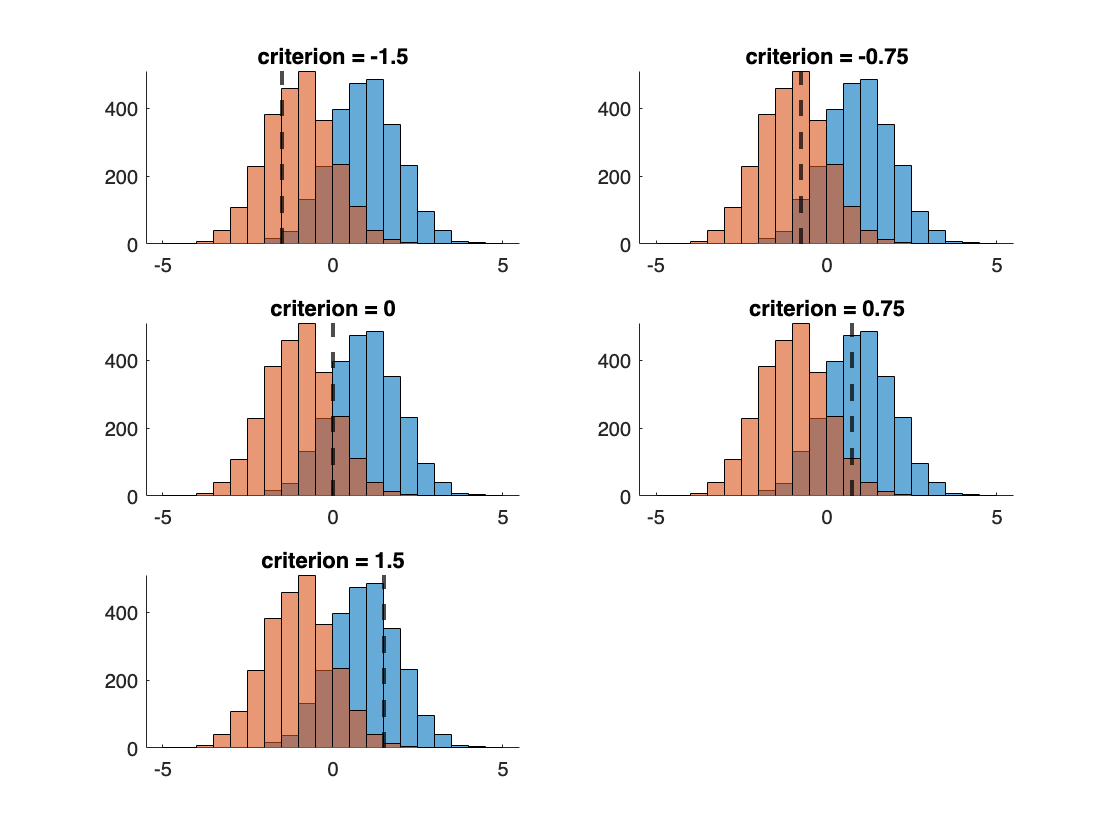

figure
histogram_bins = -5:.5:5;

% loop through different criterion values
changing_criterion = -1.5:.75:1.5;
n_criteria = length(changing_criterion);
for cc=1:n_criteria
    subplot(3,2,cc); hold on
    histogram(internal_signal(trial_type==1),histogram_bins)  % present
    histogram(internal_signal(trial_type==0),histogram_bins)  % absent
    xline(changing_criterion(cc),'k--','LineWidth',2)  % criterion
    title(sprintf('criterion = %g', changing_criterion(cc)))
    ylim([0,histogram_max])
    box off;
end

drawnow

***Learning check:*** Can you identify which areas in each subplot correspond to each of our four possible trial outcomes: hits, misses, false alarms, and correct rejections?

### Step 2. Move the criterion and analyze the results

Now that you've developed some ideas about what you expect to find, let's repeat the calculations we did above for several different decision criteria.

% choose a set of criterion values
changing_criterion = -1.5:.75:1.5;

% set up arrays for storing results
n_criteria = length(changing_criterion);
cc_hit_rate = nan(1,n_criteria);
cc_fa_rate = nan(1,n_criteria);
cc_d_prime = nan(1,n_criteria);

% loop over criterion values
for cc=1:n_criteria
    % determine the observer's response per trial
    these_responses = internal_signal >= changing_criterion(cc);
    
    % compute hit and false alarm rates
    cc_hit_rate(cc) = sum(these_responses(trial_type==1)==1)/n_present;
    cc_fa_rate(cc) = sum(these_responses(trial_type==0)==1)/n_absent;

    % compute d'
    cc_d_prime(cc) = icdf('norm',cc_hit_rate(cc),0,1) - ...
        icdf('norm',cc_fa_rate(cc),0,1);
end

#### What is the criterion's impact on hit and false alarm rates?

Two of our key measures are the observer's hit and false alarm rates, so let's plot how both change with the decision criterion.

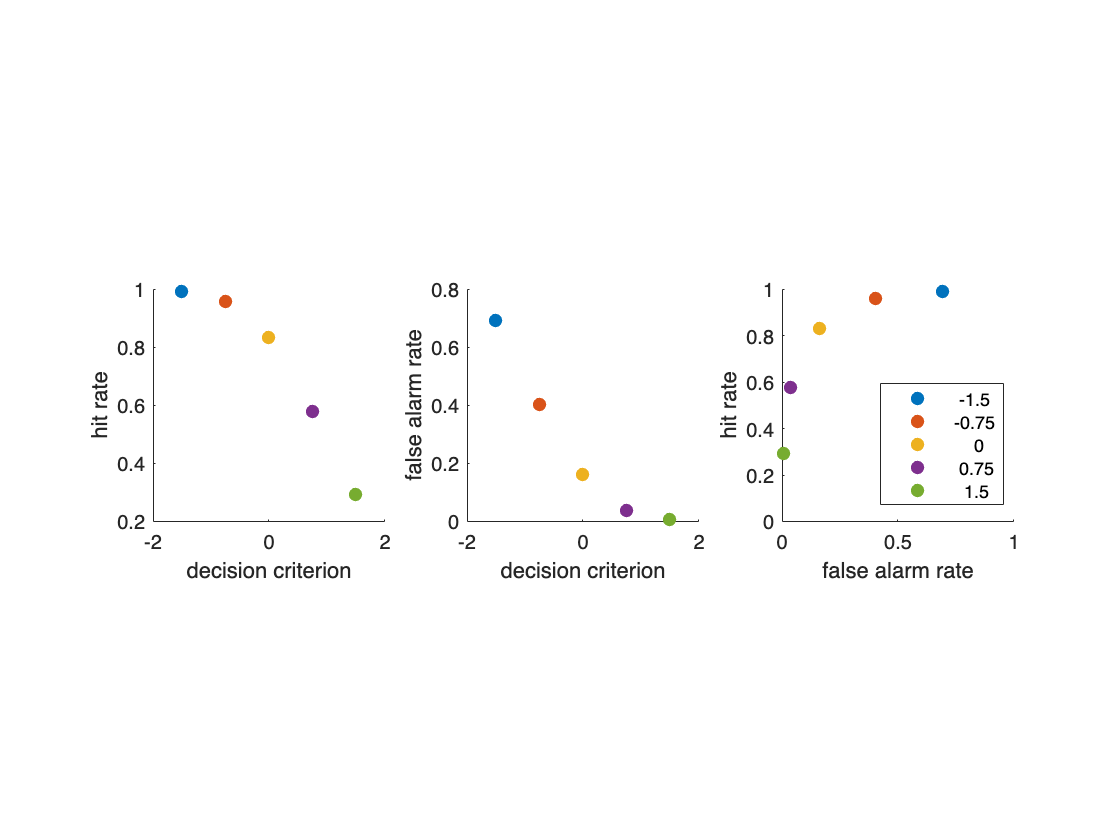

figure

% first, plot criterion vs. hit rate
subplot(131); hold on
for cc=1:n_criteria
    plot(changing_criterion(cc),cc_hit_rate(cc),'.','MarkerSize',20);
end
xlabel('decision criterion'); ylabel('hit rate')
box off; axis square;

% second, plot criterion vs. false alarm rate
subplot(132); hold on
for cc=1:n_criteria
    plot(changing_criterion(cc),cc_fa_rate(cc),'.','MarkerSize',20);
end
xlabel('decision criterion'); ylabel('false alarm rate')
box off; axis square;

% third, plot false alarm rate vs. hit rate
subplot(133); hold on
for cc=1:n_criteria
    plot(cc_fa_rate(cc),cc_hit_rate(cc),'.','MarkerSize',20);
end
legend(num2str(changing_criterion.'), 'Location','southeast')
xlabel('false alarm rate'); ylabel('hit rate')
xlim([0,1]); ylim([0,1])
box off; axis square;

drawnow

Notice anything interesting? Anything unexpected?

#### What is the criterion's impact on d'?

You've probably noticed that the observer's hit and false alarm rates change systematically with the decision criterion. Can the same be said for d'?

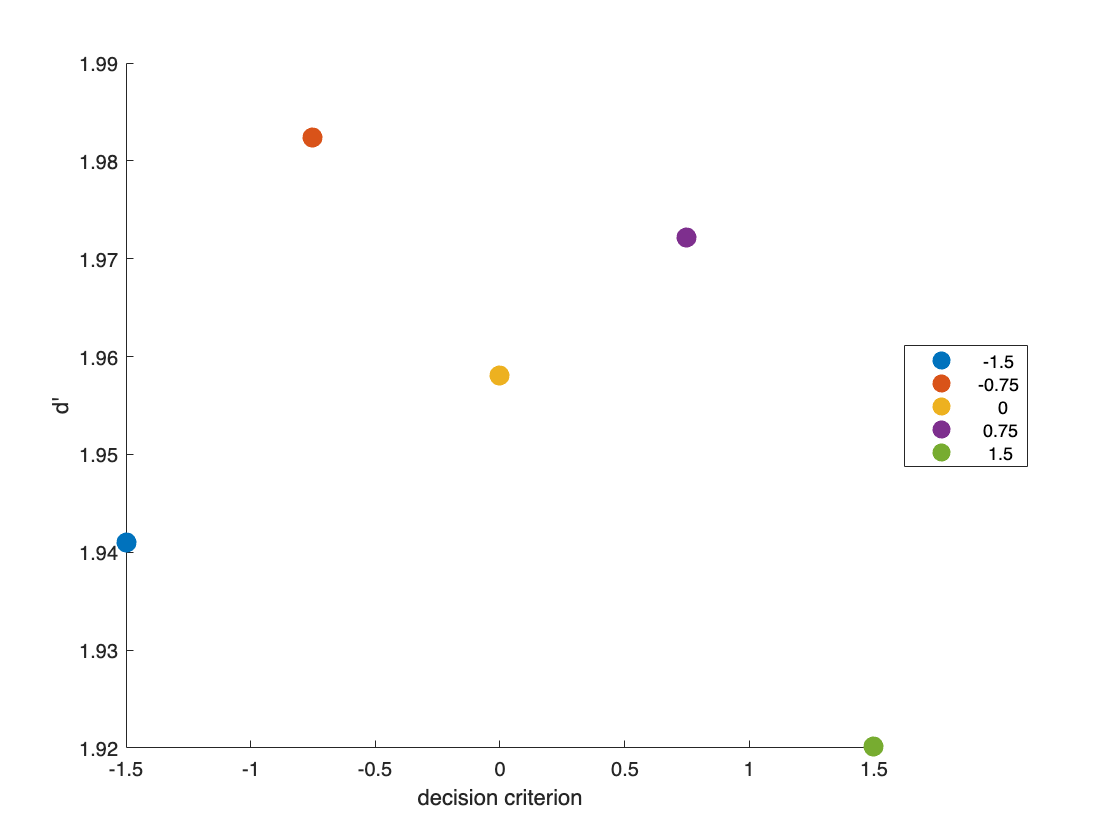

figure; hold on
for cc=1:n_criteria
    plot(changing_criterion(cc),cc_d_prime(cc),'.','MarkerSize',30);
end
legend(num2str(changing_criterion.'), 'Location','eastoutside')
xlabel('decision criterion'); ylabel("d'")
box off

drawnow

What do you think? Is there a systematic relationship?

### Step 3. Increase your sample size

Drawing conclusions from a small sample size has led many researchers astray, so let's repeat our tests for lots more criterion values.

% choose a set of criterion values
changing_criterion = -1.5:.1:1.5;

% set up arrays for storing results
n_criteria = length(changing_criterion);
cc_hit_rate = nan(1,n_criteria);
cc_fa_rate = nan(1,n_criteria);
cc_d_prime = nan(1,n_criteria);

% loop over criterion values
for cc=1:n_criteria
    % determine the observer's response per trial
    these_responses = internal_signal >= changing_criterion(cc);
    
    % compute hit and false alarm rates
    cc_hit_rate(cc) = sum(these_responses(trial_type==1)==1)/n_present;
    cc_fa_rate(cc) = sum(these_responses(trial_type==0)==1)/n_absent;

    % compute d'
    cc_d_prime(cc) = icdf('norm',cc_hit_rate(cc),0,1) - ...
        icdf('norm',cc_fa_rate(cc),0,1);
end

#### What is the criterion's impact on d'?

Let's switch things up and start by plotting d' this go-round.

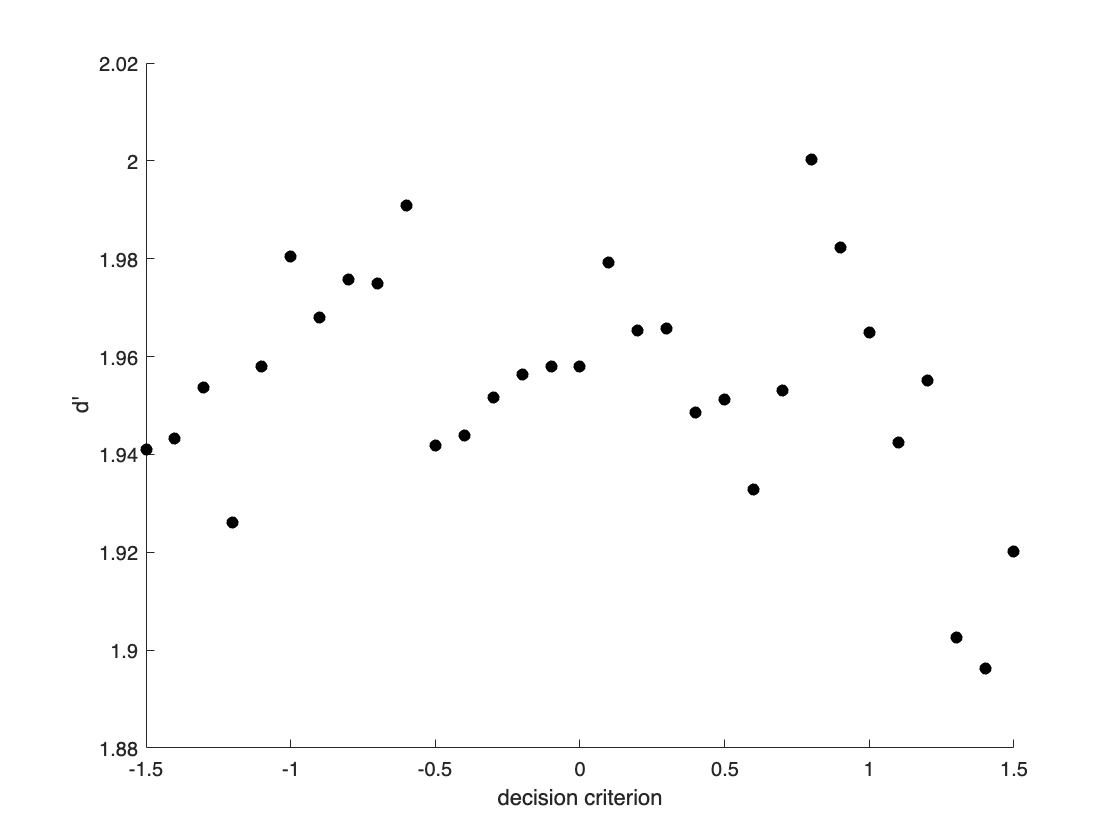

figure; hold on
scatter(changing_criterion,cc_d_prime,'k','filled');
xlabel('decision criterion'); ylabel("d'")
box off

Do the additional data points change your opinion?

What's your final verdict? Is there a systematic relationship between an observer's decision criterion and d'? Yes or no?

#### What is the criterion's impact on hit and false alarm rates?

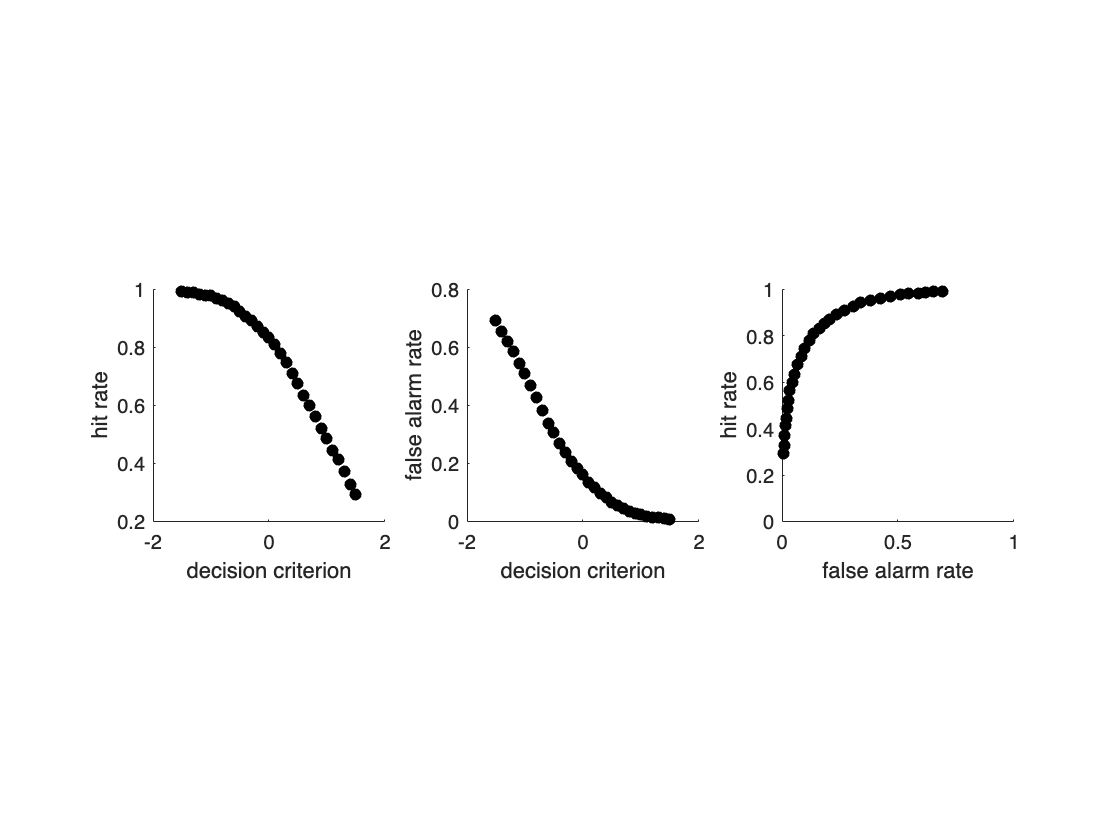

figure

% first, plot criterion vs. hit rate
subplot(131); hold on
scatter(changing_criterion,cc_hit_rate,'k','filled')
xlabel('decision criterion'); ylabel('hit rate')
box off; axis square;

% second, plot criterion vs. false alarm rate
subplot(132); hold on
scatter(changing_criterion,cc_fa_rate,'k','filled')
xlabel('decision criterion'); ylabel('false alarm rate')
box off; axis square;

% third, plot false alarm rate vs. hit rate
subplot(133); hold on
scatter(cc_fa_rate,cc_hit_rate,'k','filled')
xlabel('false alarm rate'); ylabel('hit rate')
xlim([0,1]); ylim([0,1])
box off; axis square;

drawnow

Do the additional data points change your opinion about these relationships?

What's your final verdict about whether there are systematic relationships between these values?

## Part D. Test the Impact of d'

Because we're simulating this experiment, we can control the properties of our observer's signal and noise distributions, thereby controlling d'. To confirm this, let's try changing the mean of our observer's noise (signal-absent) distribution.

% choose a set of noise distribution means
changing_mean = 1:-.5:-2;
n_means = length(changing_mean);

% calculate resulting "true" d' values
cmu_true_d_prime = (dist_mean_present - changing_mean) ./ dist_stdev;

% choose a set of criterion values
changing_criterion = -2:.1:2;
n_criteria = length(changing_criterion);

% set up arrays for storing results
cmu_internal_signal = nan(n_trials,n_means);
cmu_hit_rate = nan(n_criteria,n_means);
cmu_fa_rate = nan(n_criteria,n_means);
cmu_d_prime = nan(n_criteria,n_means);

% loop over every mean
for mm=1:n_means
    % loop over every trial, simulating observer's percept for each
    for ii=1:n_trials
      if trial_type(ii) == 1
        cmu_internal_signal(ii,mm) = random('norm',dist_mean_present,dist_stdev);
      else
        cmu_internal_signal(ii,mm) = random('norm',changing_mean(mm),dist_stdev);
      end
    end
    
    % loop over criterion values
    for cc=1:n_criteria
        % determine the observer's response per trial
        these_responses = cmu_internal_signal(:,mm) >= changing_criterion(cc);
        
        % compute hit and false alarm rates
        cmu_hit_rate(cc,mm) = sum(these_responses(trial_type==1)==1)/n_present;
        cmu_fa_rate(cc,mm) = sum(these_responses(trial_type==0)==1)/n_absent;
    
        % compute d'
        cmu_d_prime(cc,mm) = icdf('norm',cmu_hit_rate(cc,mm),0,1) - ...
            icdf('norm',cmu_fa_rate(cc,mm),0,1);
    end
end

### Step 1. Compare "true" and simulated d' values

First, let's make sure that the d' values we calculated from our simulations match up with what they should be, based on the distribution parameters that we defined.

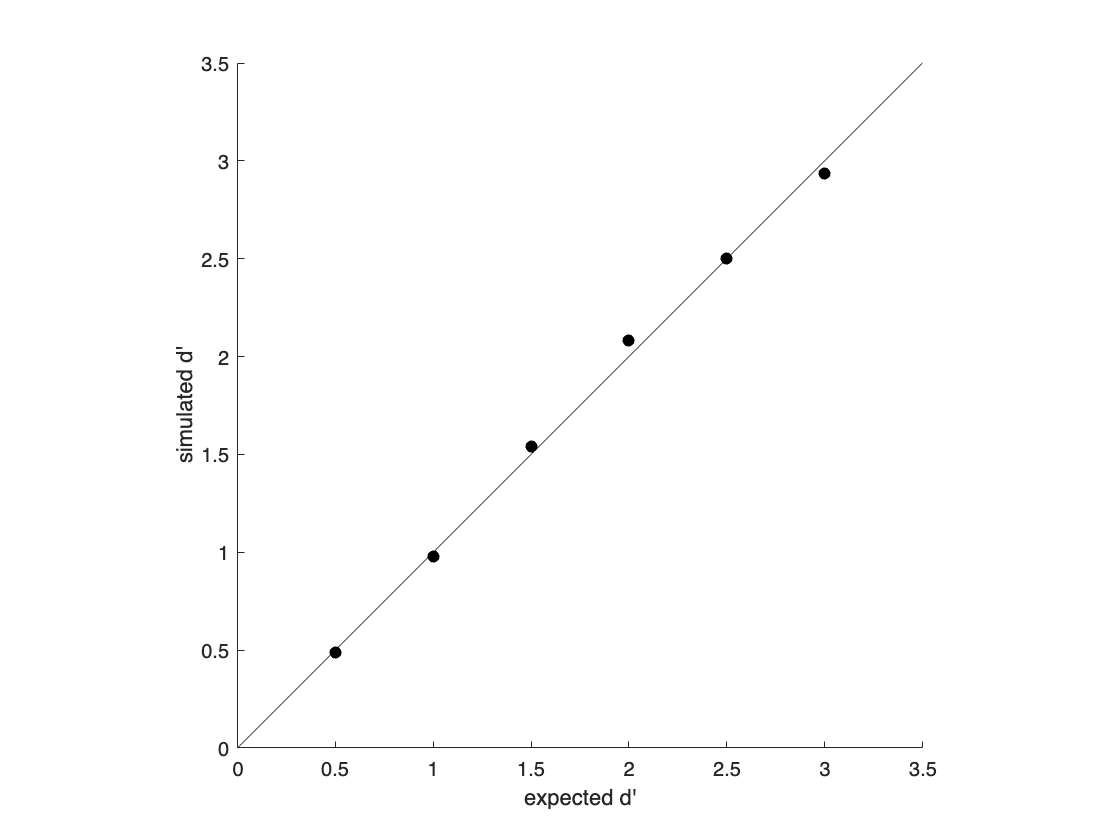

figure; hold on
scatter(cmu_true_d_prime,median(cmu_d_prime,1),'k','filled')  % use median across criterion values
plot([0,3.5],[0,3.5],'k-')  % line of equality
xlabel("expected d'")
ylabel("simulated d'")
xlim([0,3.5]); ylim([0,3.5])
box off; axis square

drawnow

### Step 2. Compare hit and false alarm rates

As you can probably tell by now, hit and false alarm rates are important values in signal dection theory, so let's see how changing d' impacts the relationship between hit rate (aka true positive rate) and false alarm rate (aka false positive rate).

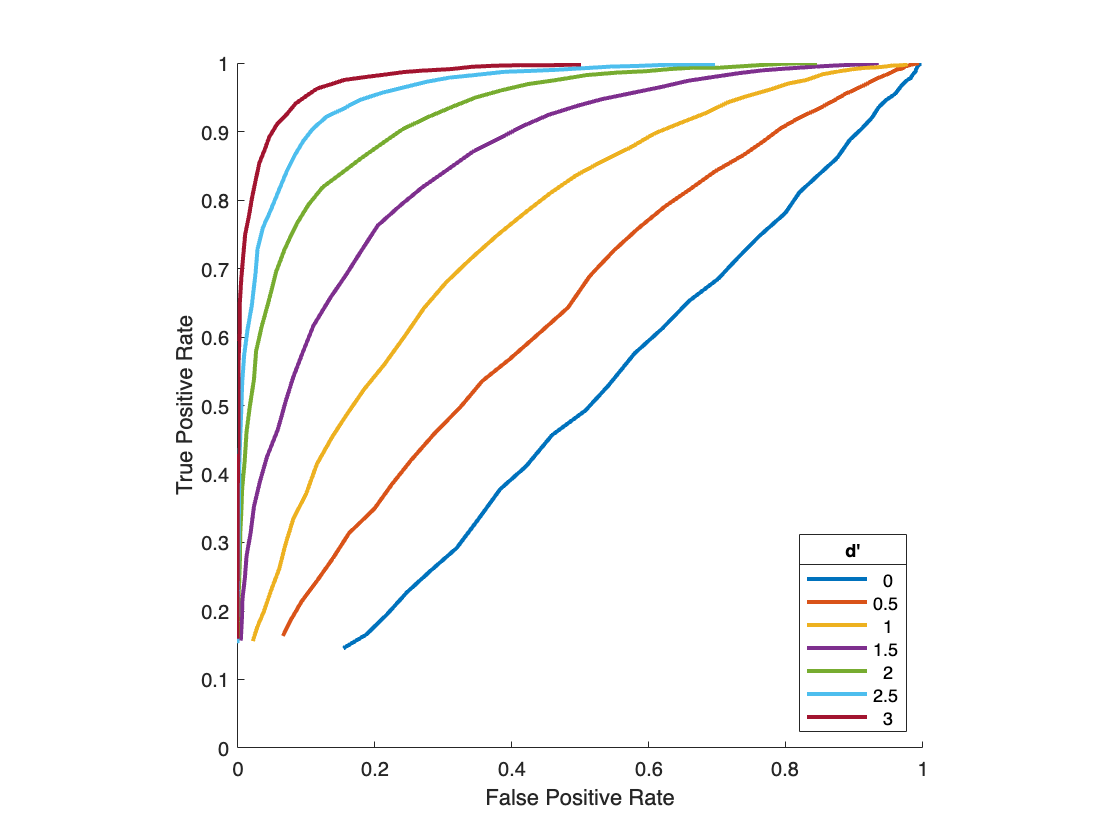

figure; hold on
for mm=1:n_means
    plot(cmu_fa_rate(:,mm),cmu_hit_rate(:,mm),'-','LineWidth',2)
end
lgd = legend(num2str(cmu_true_d_prime.'), 'Location','southeast');
title(lgd, "d'")
xlabel('False Positive Rate'); ylabel('True Positive Rate')
xlim([0,1]); ylim([0,1])
box off; axis square;

drawnow

The curves you've just plotted are called receiver operating characteristic (ROC) curves. You draw one by plotting the false positive rate vs. the true positive rate as a function of the decision criterion. In other words, you generate an ROC curve by changing the decision criterion.

What do you notice about the relationship between d' and the ROC curve?